# Comparison of V27 Blade Planform Models and OpenFAST Model

## 2014/2015 FASTv7 V27 Model

%Based on Resor 2014 FASTv7 model (Version 20151110)

%original turibne model: Resor, B. and LeBlanc, B. “An Aeroelastic Reference Model for the SWIFT Turbines,” SAND2014-19136.

RNodes_2014  = [  %RNodes is relative to the rotor hub center
 0.82500
 1.47500
 2.12500
 2.77500
 3.42500
 4.07500
 4.72500
 5.37500
 6.02500
 6.67500
 7.32500
 7.97500
 8.62500
 9.27500
 9.92500
10.57500
11.22500
11.87500
12.52500
13.17500];

AeroTwst_2014 = [
14.77   
13.81   
12.83   
11.78   
10.72   
 9.67   
 8.62   
 7.57   
 6.51   
 5.67   
 4.93   
 4.19   
 3.45   
 2.71   
 1.98   
 1.58   
 1.23   
 0.88   
 0.53   
 0.18   ];

Chord_2014 = [
0.589
0.979
1.285
1.239
1.192
1.146
1.099
1.053
1.006
0.960
0.913
0.866
0.820
0.773
0.726
0.680
0.633
0.587
0.540
0.493];


## Updated 2018 FAStv7 V27 model


%Chris Kelley update 2018, Kelley, C. and White, J. “An update to the SWiFT V27 Reference Model,” SAND2018-11893.
%Based on Resor 2014 FASTv7 model with corrections based on actual blade measurements documented in the Kelley 2018 report.
%original turibne model: Resor, B. and LeBlanc, B. “An Aeroelastic Reference Model for the SWIFT Turbines,” SAND2014-19136.
%V27_v7%SNLV27_AD_mod.ipt

RNodes  = [  %RNodes is relative to the rotor hub center
 0.82500
 1.47500
 2.12500
 2.77500
 3.42500
 4.07500
 4.72500
 5.37500
 6.02500
 6.67500
 7.32500
 7.97500
 8.62500
 9.27500
 9.92500
10.57500
11.22500
11.87500
12.52500
13.17500];

AeroTwst = [
13.9573 
13.0025 
12.0596 
11.1288 
10.2102 
9.3046  
8.3928  
7.4834  
6.6249  
5.8527  
5.1189  
4.4182  
3.7563  
3.1393  
2.5731  
2.0579  
1.5793  
1.1394  
0.7418  
0.3900  ];

DRNodes = [
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000];

 Chord = [  
 0.589 
 0.979 
 1.2728
 1.2276
 1.1823
 1.1368
 1.091 
 1.045 
 0.999 
 0.953 
 0.9072
 0.8614
 0.8155
 0.7694
 0.7231
 0.6764
 0.6295
 0.5823
 0.5348
 0.4871];

NFoil = [
  1  
  2  
  2  
  2  
  2  
  3  
  3  
  3  
  3  
  3  
  3  
  3  
  4  
  4  
  4  
  4  
  4  
  4  
  5  
  5  ];


## OF Model 1

% This is the model created during the summer of 2018 for OpenFAST.  There was something wrong with the interpolation.

  BlSpn = [ %Relative to blade root (0.5m from hub center)
0
0.68
1.37
2.05
2.74
3.42
4.11
4.79
5.47
6.16
6.84
7.53
8.21
8.89
9.58
10.26
10.95
11.63
12.32
13];

BlTwist = [ 
1.40E+01
1.30E+01
1.21E+01
1.11E+01
1.02E+01
9.30E+00
8.39E+00
7.48E+00
6.62E+00
5.85E+00
5.12E+00
4.42E+00
3.76E+00
3.14E+00
2.57E+00
2.06E+00
1.58E+00
1.14E+00
7.42E-01
3.90E-01];

BlChord  = [
5.89E-01
9.79E-01
1.27E+00
1.23E+00
1.18E+00
1.14E+00
1.09E+00
1.05E+00
9.99E-01
9.53E-01
9.07E-01
8.61E-01
8.16E-01
7.69E-01
7.23E-01
6.76E-01
6.30E-01
5.82E-01
5.35E-01
4.87E-01];


## Ideal profile to interp to

% This blade planform is modified form kelley's 2018 update, mainly adding the 2m station for improved OpenFAST interpolation due to the change in node locations.  The 2m station is max chord according to Resor's 2014 report.  Resor estimated the max chord ot be 1.29m based on past documentation.  The measured values from Kelley were used here instead.

%Adding max chord from Resor report R=2m, Chord=1.29m

RNodesI  = [
 0.82500
 1.47500
 2.00
 2.12500
 2.77500
 3.42500
 4.07500
 4.72500
 5.37500
 6.02500
 6.67500
 7.32500
 7.97500
 8.62500
 9.27500
 9.92500
10.57500
11.22500
11.87500
12.52500
13.17500];

AeroTwstI = [
13.9573 
13.0025 
12.245 %Taken from Kelley2018 report as average measured form blades 1 and 2.  interp1([1.475, 2.125],[13.0025, 12.0596],2) gives 12.2409 deg to be linearly smooth, 
12.0596 
11.1288 
10.2102 
9.3046  
8.3928  
7.4834  
6.6249  
5.8527  
5.1189  
4.4182  
3.7563  
3.1393  
2.5731  
2.0579  
1.5793  
1.1394  
0.7418  
0.3900  ];

DRNodesI = [
 0.65000
 0.65000
 99999
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000
 0.65000];

 ChordI = [  
 0.589 
 0.979 
 1.2815 %Taken from Kelley2018 report  %interp1([2.125, 2.7750 ],[1.2728, 1.2276],2,'linear','extrap'),  Resor document shows 1.29m chord at 2 m span, but this value isn't smooth with the rest of the blade.
 1.2728
 1.2276
 1.1823
 1.1368
 1.091 
 1.045 
 0.999 
 0.953 
 0.9072
 0.8614
 0.8155
 0.7694
 0.7231
 0.6764
 0.6295
 0.5823
 0.5348
 0.4871];

## Interpolate new OpenFAST blade

Based on updated blade planform from Chris Kelley's 2018 report and FASTv7 model.

nodes = 27;
BldLength = 13.0;
BLSpn4 = (0:BldLength/(nodes-1):BldLength)';  %Relative to blade root (0.5m from hub center)
BLSpn_Rt4 = BLSpn4 +0.5;  %Relative to rotor hub center
Chord4 = interp1(RNodesI, ChordI, BLSpn_Rt4,'linear','extrap');
Twist4 = interp1(RNodesI, AeroTwstI, BLSpn_Rt4,'linear','extrap');

%Airfoil ID set to match the FASTv7 2018 V27 model
BlAFID = [
    1
2
2
2
2
2
3
3
3
3
3
3
3
3
3
3
4
4
4
4
4
4
4
4
5
5
5];


% Save results to a table
T = table(BLSpn4, Twist4, Chord4, BlAFID,...
    'VariableNames',{'BlSpn' 'BlTwist' 'BlChord' 'BlAFID' })

T =     BlSpn    BlTwist    BlChord    BlAFID
    _____    _______    _______    ______

       0      14.435      0.394    1     
     0.5        13.7      0.694    2     
       1      12.966     0.9934    2     
     1.5      12.245     1.2815    2     
       2      11.523     1.2467    2     
     2.5      10.811     1.2119    2     
       3      10.106      1.177    3     
     3.5      9.4091     1.1421    3     
       4      8.7084     1.1069    3     
     4.5      8.0081     1.0715    3     
       5      7.3183     1.0362    3     
     5.5      6.6579     1.0008    3     
       6      6.0606    0.96538    3     
     6.5      5.4858     0.9301    3     
       7      4.9303    0.89487    3     
     7.5      4.3927    0.85963    3     
       8      3.8836    0.82433    4     
     8.5      3.4003     0.7889    4     
       9      2.943

T.Properties.VariableUnits = {'m-from-root' 'deg.' 'm' '-' };
writetable(T, 'OpenFAST_Blade.csv');
TF = table(num2str(BLSpn4,'%.3f'), num2str(Twist4,'%.3f'), num2str(Chord4,'%.4f'),num2str(BlAFID,'%.0f'),...
    'VariableNames',{'BlSpn' 'BlTwist' 'BlChord' 'BlAFID' })

TF =     BlSpn     BlTwist    BlChord    BlAFID
    ______    _______    _______    ______

     0.000    14.435     0.3940     1     
     0.500    13.700     0.6940     2     
     1.000    12.966     0.9934     2     
     1.500    12.245     1.2815     2     
     2.000    11.523     1.2467     2     
     2.500    10.811     1.2119     2     
     3.000    10.106     1.1770     3     
     3.500     9.409     1.1421     3     
     4.000     8.708     1.1069     3     
     4.500     8.008     1.0715     3     
     5.000     7.318     1.0362     3     
     5.500     6.658     1.0008     3     
     6.000     6.061     0.9654     3     
     6.500     5.486     0.9301     3     
     7.000     4.930     0.8949     3     
     7.500     4.393     0.8596     3     
     8.000     3.884     0.8243     4     
     8.500     3.400     0.7889     4    

TF.Properties.VariableUnits = {'m-from-root' 'deg.' 'm' '-'};
writetable(TF, 'OpenFAST_Blade','Delimiter','\t');



## Compare

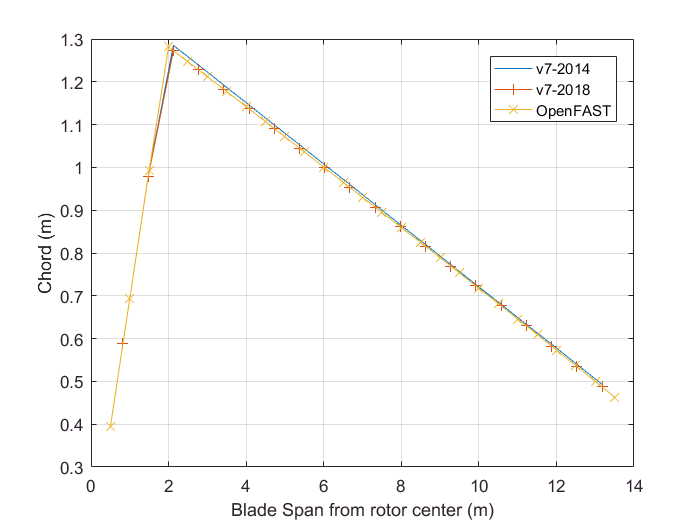


BLSpn_Rt = RNodes - DRNodes./2;

BLSpn_Rt(21) = RNodes(20)    + DRNodes(20)./2;

%Plot with Bad OpenFAST version
%figure;
%plot(RNodes_2014, Chord_2014,RNodes, Chord,'+-', BlSpn+0.5, BlChord,BLSpn_Rt4,Chord4,'x-');
%legend('v7-2014','v7-2018','OF-v1','OF-Interp4')
%figure;
%plot(RNodes_2014, AeroTwst_2014, RNodes, AeroTwst,'+-', BlSpn+0.5, BlTwist, BLSpn_Rt4,Twist4,'x-');
%legend('v7-2014','v7-2018','OF-v1','OF-Interp4')

%Plot without Bad OpenFAST version
figure;
plot(RNodes_2014, Chord_2014,RNodes, Chord,'+-', BLSpn_Rt4,Chord4,'x-');
grid on; xlabel('Blade Span from rotor center (m)'); ylabel('Chord (m)');
legend('v7-2014','v7-2018','OpenFAST')

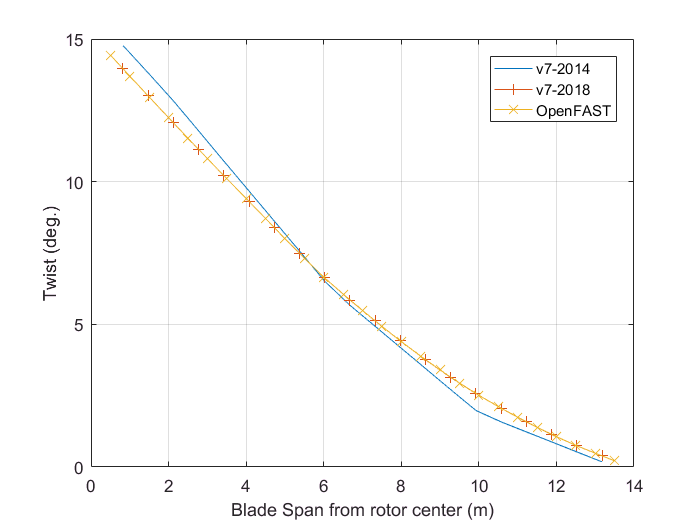

figure;
plot(RNodes_2014, AeroTwst_2014, RNodes, AeroTwst,'+-',  BLSpn_Rt4,Twist4,'x-');
grid on; xlabel('Blade Span from rotor center (m)'); ylabel('Twist (deg.)');
legend('v7-2014','v7-2018','OpenFAST')